# Time Domain Specifications 

Time domain Specifications - second order control system


$$C\left(s\right)=\frac{\omega_n^2 }{s^2 +2\omega_n \zeta s+\omega_n^2 }$$


Wn = 6% Wn - rad/sec

Wn = 6

zeta = 0.3% damping ratio 

zeta = 0.3000

## Trasnfer Function 

C = tf(Wn*Wn, [1 2*zeta*Wn Wn*Wn])


C =
 
         36
  ----------------
  s^2 + 3.6 s + 36
 
Continuous-time transfer function.
Model Properties


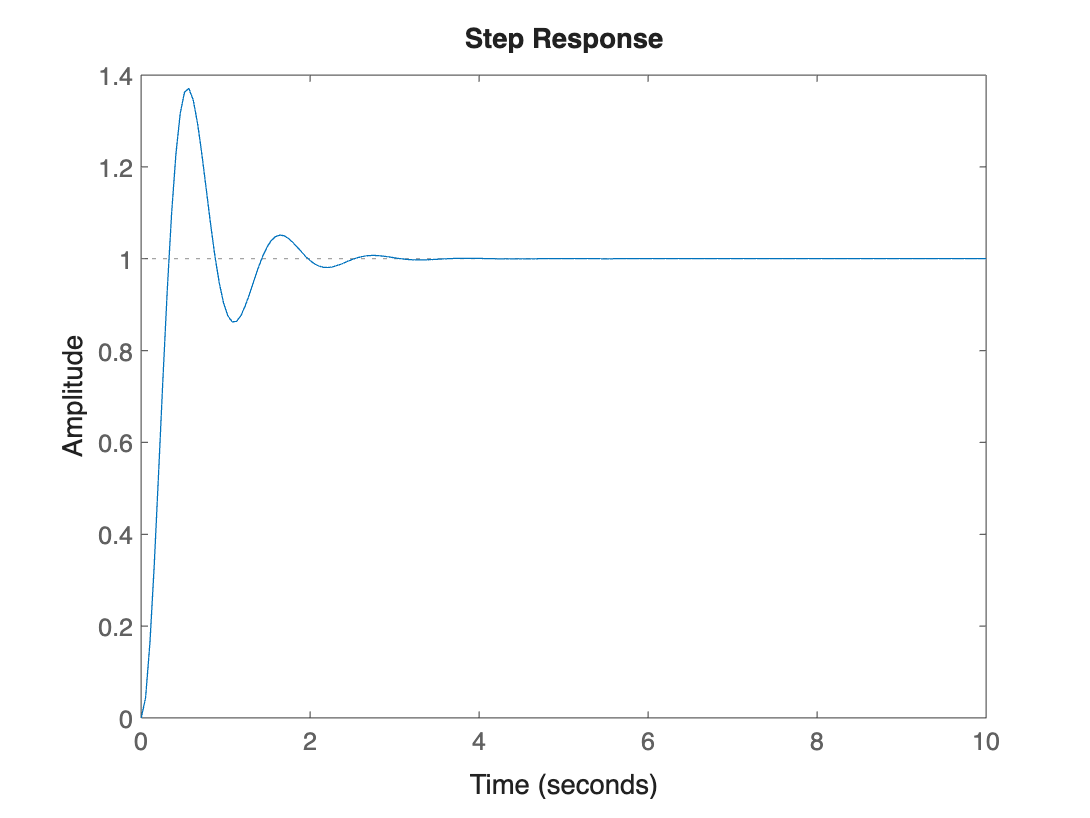

stepplot(C,10)

%stepinfo(C)

## Time Domain Specifications

omega_d = Wn*sqrt(1 - zeta^2);
t_r = (pi - acos(zeta)) / omega_d; % Rise time
t_p = pi / omega_d;               % Peak time
M_p = exp(-zeta * pi / sqrt(1 - zeta^2)) * 100; % Maximum overshoot
t_s_2percent = 4 / (zeta * Wn); % Settling time (2%)
t_s_5percent = 3 / (zeta * Wn); % Settling time (5%)

disp('Time-Domain Specifications (Computed by Formulas):');

Time-Domain Specifications (Computed by Formulas):


disp(['Rise Time (t_r): ', num2str(t_r), ' seconds']);

Rise Time (t_r): 0.32767 seconds


disp(['Peak Time (t_p): ', num2str(t_p), ' seconds']);

Peak Time (t_p): 0.54888 seconds


disp(['Maximum Overshoot (M_p): ', num2str(M_p), ' %']);

Maximum Overshoot (M_p): 37.2326 %


disp(['Settling Time (2% criterion, t_s): ', num2str(t_s_2percent), ' seconds']);

Settling Time (2% criterion, t_s): 2.2222 seconds


disp(['Settling Time (5% criterion, t_s): ', num2str(t_s_5percent), ' seconds']);

Settling Time (5% criterion, t_s): 1.6667 seconds
